clc; clear;

% Define the function to integrate
f = @(x) x.^5;  % Example: Gaussian
% You can try others like: @(x) sin(pi*x), @(x) 1./(1 + 25*x.^2), etc.

n = 2; % Number of Gauss–Legendre points

% Get Gauss–Legendre points and weights on [-1, 1]
[xi, w] = lgwt(n, -1, 1);  
xi = flip(xi)

xi =    -0.5774
    0.5774


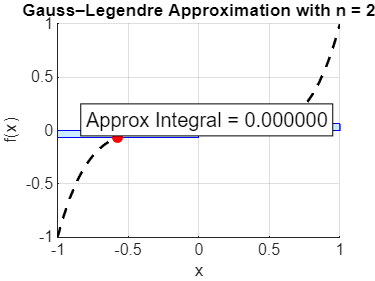


% Evaluate function at Gauss points
fi = f(xi);

% Plot setup
figure; hold on; grid on;
xlabel('x'); ylabel('f(x)');
title(['Gauss–Legendre Approximation with n = ', num2str(n)]);

% Plot the actual function
fplot(f, [-1, 1], 'k--', 'LineWidth', 1.5);

% Draw rectangles centered at xi with width based on neighbors and height f(xi)
for i = 1:n
    % Determine width of the rectangle
    if i == 1
        x_left = -1;
    else
        x_left = (xi(i-1) + xi(i))/2;
    end
    if i == n
        x_right = 1;
    else
        x_right = (xi(i) + xi(i+1))/2;
    end
    width = x_right - x_left;
    
    % Rectangle corners
    x_rect = [x_left, x_right, x_right, x_left];
    y_rect = [0, 0, fi(i), fi(i)];

    % Draw rectangle
    fill(x_rect, y_rect, [0.5 0.8 1], 'EdgeColor', 'b', 'FaceAlpha', 0.4);

    % Mark Gauss point
    plot(xi(i), fi(i), 'ro', 'MarkerFaceColor', 'r');
end

%Optional: display numerical integral
I_approx = sum(w .* fi);
text(-0.8, 0.1, sprintf('Approx Integral = %.6f', I_approx), ...
    'FontSize', 12, 'BackgroundColor', 'w', 'EdgeColor', 'k');